load GDP.mat
GDPtable = GDP{:,2:end};
Avg = nanmean(GDPtable);
Var = var(GDPtable);
CoeV = nanstd(GDPtable)./Avg;

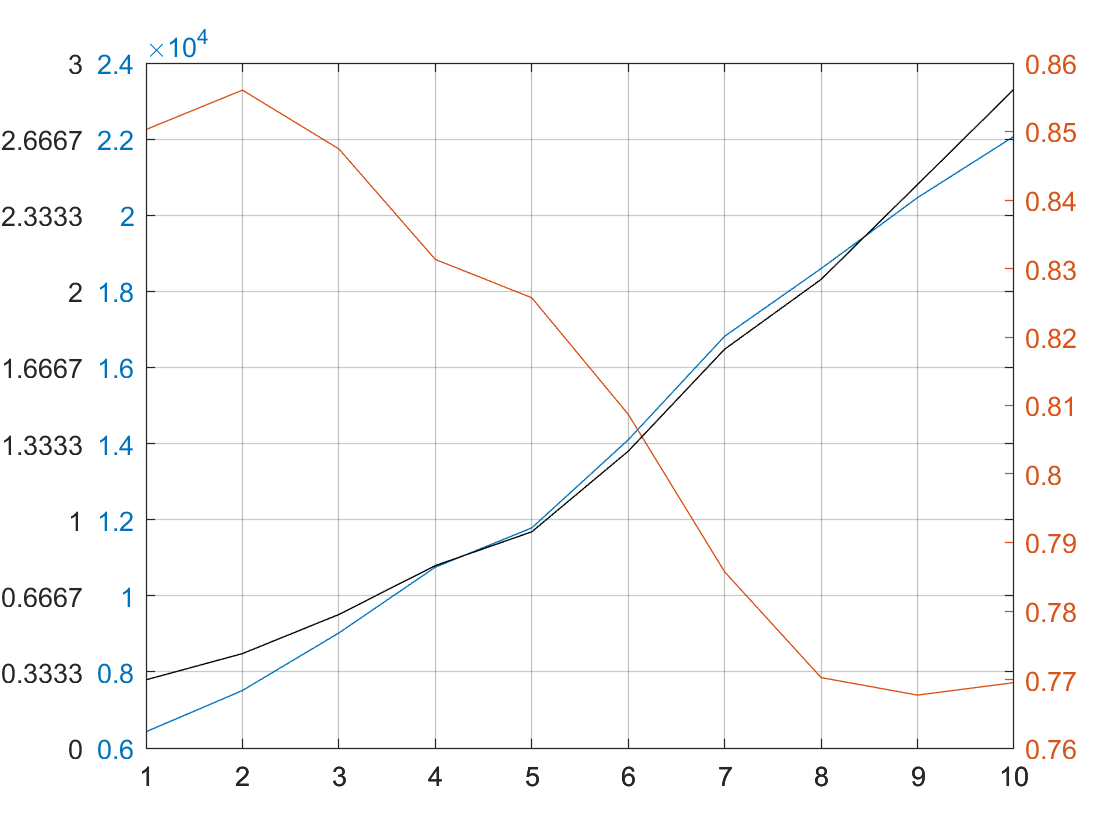

x = 1:10;
y1 = Avg;
y2 = CoeV;
y3 = Var;
% Plot on the left and right y axes
figure
ax1 = axes;
yyaxis left                 % see [1]
plot(x,y1)
pause(0.1)                  % see [3]
% set the y(left) and x tick values, make them permanent
% This is the tricky part and shoudl receive a lot of thought when
% you adapt this to your code...
ax1.XTickMode = 'manual';
ax1.YTickMode = 'manual';
ax1.YLim = [min(ax1.YTick), max(ax1.YTick)];  % see [4]
ax1.XLimMode = 'manual';
grid(ax1,'on')
ytick = ax1.YTick;
yyaxis right                % see [1]
plot(x,y2)
% create 2nd, transparent axes
ax2 = axes('position', ax1.Position);
plot(ax2,x,y3, 'k')
pause(0.1)                 % see [3]
ax2.Color = 'none';
grid(ax2, 'on')
% Horizontally scale the y axis to alight the grid (again, be careful!)
ax2.XLim = ax1.XLim;
ax2.XTick = ax1.XTick;
ax2.YLimMode = 'manual';
yl = ax2.YLim;
ax2.YTick = linspace(yl(1), yl(2), length(ytick));      % see [2]
% horzontally offset y tick labels
ax2.YTickLabel = strcat(ax2.YTickLabel, {'       '});

load chap3.mat
chap3table=chap3{:,2:end};
sum3 = sum(chap3table);
chap3table = chap3table ./sum3;
sum4 = sum(chap3table);


%x1=0:0.1:1;
x1=linspace(0,1,10);
figure;
plot(x1,x1,'b-.');
hold on
JNS=zeros(6,1);
for j=1:6
    x2=0:0.001:1;
    t=chap3table(:,j)';
    t,i=sort(t,"descend");
    xlen=length(x1);
    y=zeros(1,xlen);
    y=cumsum(t);
    y=[0,y];
    c=fit(x1',y','smoothingspline');
    d=c(x2);
    plot(x1,y,'*',x2,d,'-')
    area1 = trapz(x2,d);
    area2 = trapz(x1,x1);
    JN = (area1-area2)/area2;
    JNS(j,1)=  JN;
end

t =     0.5673    0.0275    0.1345    0.0256    0.0577    0.0154    0.0520    0.0730    0.0471


t =     0.5559    0.0223    0.0927    0.0311    0.0762    0.0276    0.0594    0.0969    0.0378


t =     0.5434    0.0253    0.0974    0.0324    0.0596    0.0292    0.0673    0.1062    0.0392


t =     0.4988    0.0221    0.1058    0.0278    0.0665    0.0272    0.0718    0.1325    0.0474


t =     0.5133    0.0205    0.0945    0.0258    0.0586    0.0283    0.0666    0.1398    0.0528


t =     0.4633    0.0222    0.1003    0.0255    0.0752    0.0242    0.0735    0.1622    0.0537


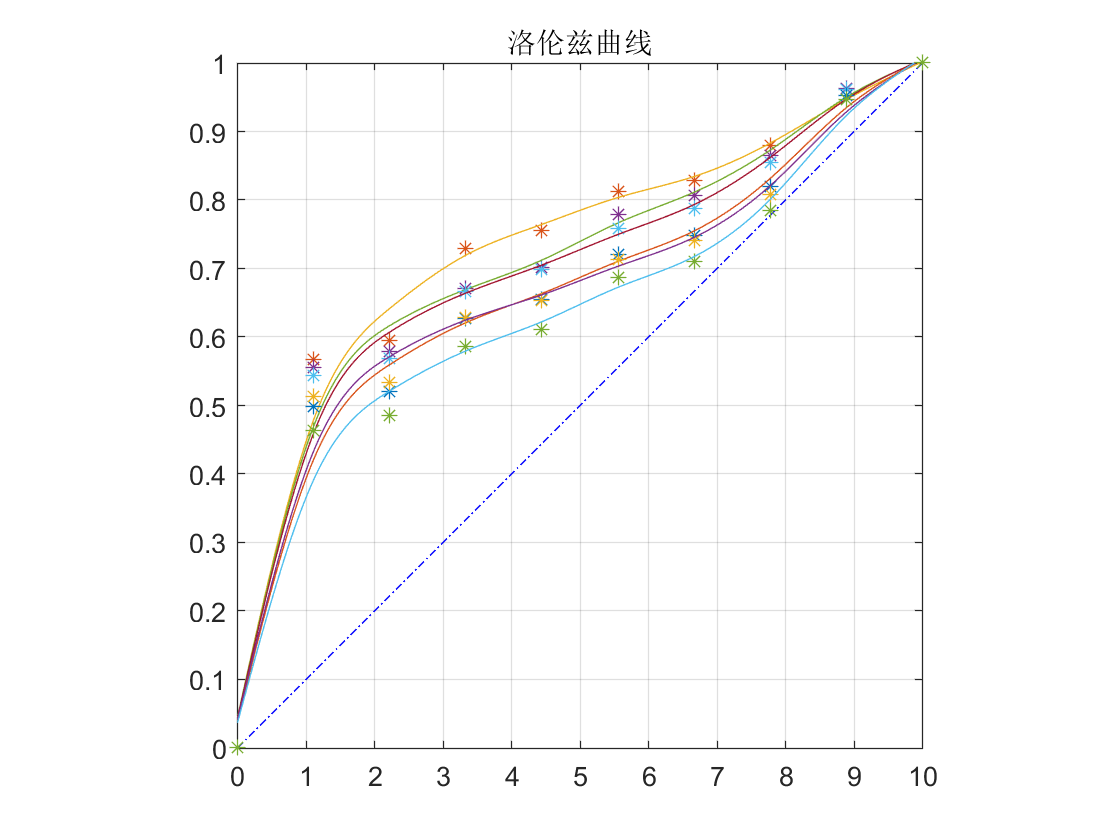


title('洛伦兹曲线')
% xlabel('人口百分比累计'),ylabel('收入百分比累计')
axis equal
axis([0,1,0,1])
set(gca,'XTick',0:0.1:1);
xticklabels([0:1:10]);
grid on

% %计算基尼系数
% area1=trapz(x2,d);
% area2=trapz(x1,x1);
% JN=area1/area2;
% disp(['收入数百分比基尼系数=',num2str(JN)])

x1=linspace(0,1,10);
figure;
% plot(x1,x1,'b-.');
% hold on
% JNS=zeros(6,1);
for j=1:6
    x2=0:0.001:1;
    t=chap3table(:,j)';
    t,i=sort(t,"descend");
    xlen=length(x1);
    y=zeros(1,xlen);
    y=cumsum(t);
    y=[0,y];
    c=fit(x1',y','smoothingspline');
    d=c(x2);
    subplot(3,2,j)
    plot(x1,x1,'b-.');
    plot(x1,y,'*',x2,d,'-')
    axis equal
    axis([0,1,0,1])
    set(gca,'XTick',0:0.1:1);
    xticklabels([0:1:10]);
    %     area1 = trapz(x2,d);
    %     area2 = trapz(x1,x1);
    %     JN = (area1-area2)/area2;
    %     JNS(j,1)=  JN;
end

t =     0.5673    0.0275    0.1345    0.0256    0.0577    0.0154    0.0520    0.0730    0.0471


t =     0.5559    0.0223    0.0927    0.0311    0.0762    0.0276    0.0594    0.0969    0.0378


t =     0.5434    0.0253    0.0974    0.0324    0.0596    0.0292    0.0673    0.1062    0.0392


t =     0.4988    0.0221    0.1058    0.0278    0.0665    0.0272    0.0718    0.1325    0.0474


t =     0.5133    0.0205    0.0945    0.0258    0.0586    0.0283    0.0666    0.1398    0.0528


t =     0.4633    0.0222    0.1003    0.0255    0.0752    0.0242    0.0735    0.1622    0.0537


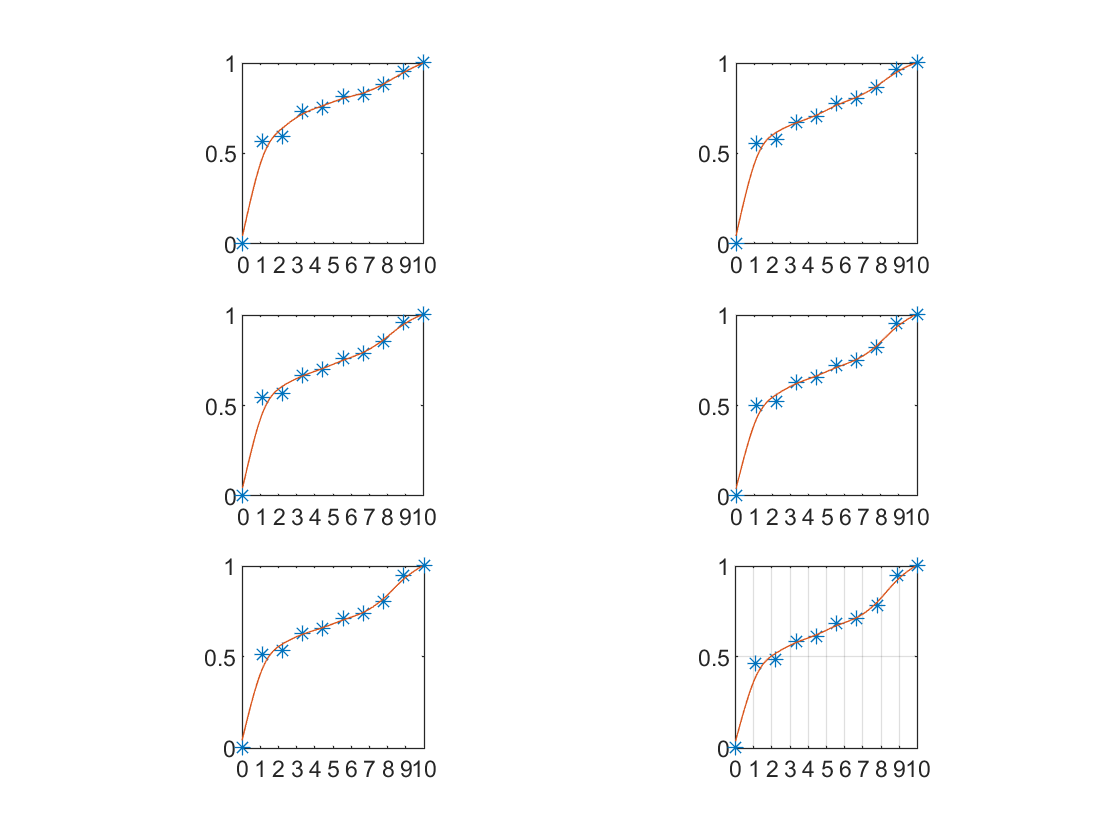


% title('洛伦兹曲线')
% xlabel('人口百分比累计'),ylabel('收入百分比累计')

grid on

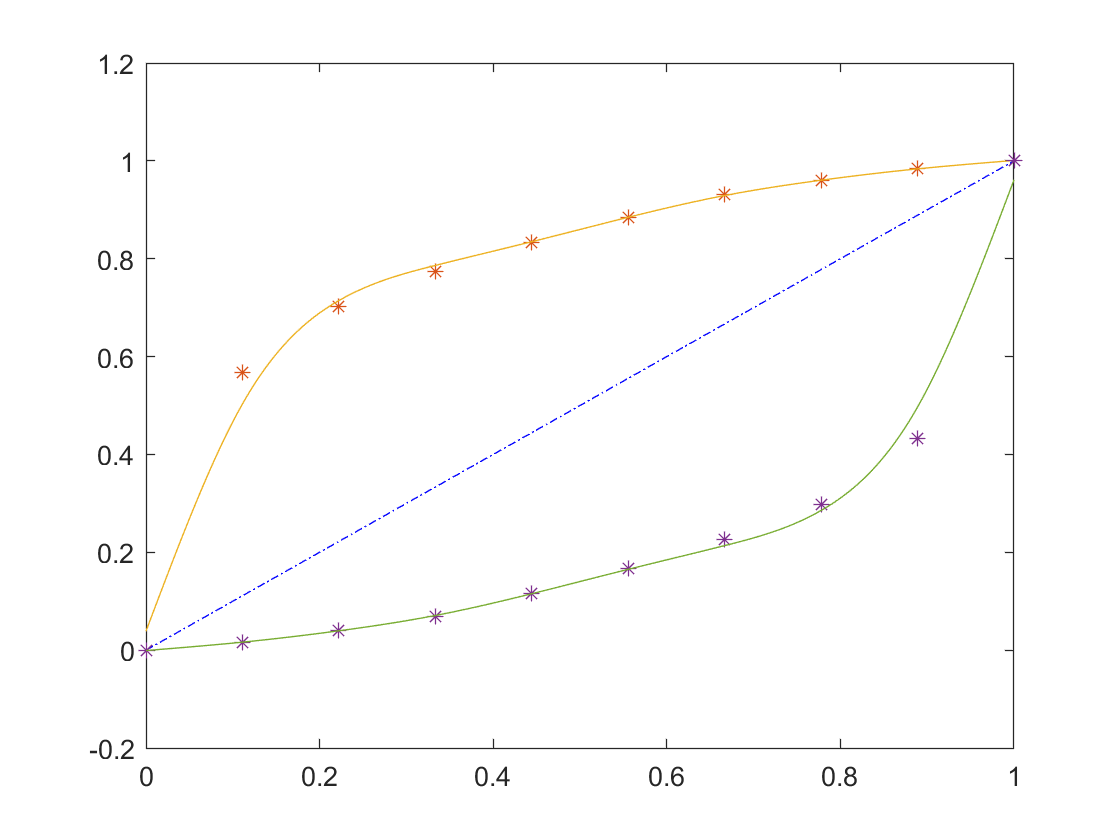

x1=linspace(0,1,10);
figure;
plot(x1,x1,'b-.');
hold on
JNS=zeros(6,1);

x2=0:0.001:1;
t1=sort(chap3table(:,1)',"descend");
xlen=length(x1);
y1=zeros(1,xlen);
y1=cumsum(t1);
y1=[0,y1];
c=fit(x1',y1','smoothingspline');
d=c(x2);
plot(x1,y1,'*',x2,d,'-')
hold on

t=sort(chap3table(:,1)',"ascend");
xlen=length(x1);
y=zeros(1,xlen);
y=cumsum(t);
y=[0,y];
c=fit(x1',y','smoothingspline');
d=c(x2);
plot(x1,y,'*',x2,d,'-')